# Analysis

## Import saved dataset

clear all;
% eeglab; close;
trial = '002-AO';

filepath = 'C:\\Users\\anhtn\\OneDrive - PennO365\\Documents\\GitHub\\analysis\\Datasets\\';
filename = [trial '-preprocessed.set']; % manually type to select dataset
EEG = pop_loadset('filename', filename, 'filepath', filepath);

pop_loadset(): loading file C:\Users\anhtn\OneDrive - PennO365\Documents\GitHub\analysis\Datasets\002-AO-preprocessed.set ...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


plot_folder = ['plot-' trial '\\' ];

###  Extract epochs and select C3, C4 electrodes

chan_names = {'C3', 'C4'};
RH_cluster = {'C4', 'FC2', 'FC6', 'F4'};
LH_cluster = {'C3', 'FC5', 'FC1', 'F3'};
all_elec = [RH_cluster LH_cluster];
elec_plot = {all_elec}; % plot PSD of EEG at all relevant electrodes

theta_band = {4:8};
alpha_l_band = {8:10};
alpha_h_band = {10:13};
beta_band = {13:30};
freq_bands = [alpha_l_band, alpha_h_band, beta_band];

freqs_array = [6,8,10,12,20,30];

markerVal_string = ["10" "11" "12" "13" "14" "15" "16" "17"...
    "20" "21" "22" "23" "24" "25" "26" "27" ...
    "30" "31" "32" "33" "34" "35" "36" "37" ...
    "40" "41" "42" "43" "44" "45" "46" "47"];
markerVal_num = [10  11  12  13  14  15  16  17 20  21  22  23  24  25  26  27  30  31  32  33  34  35  36  37  40  41  42  43  44  45  46  47];
markerLabel = ["human-left", "human-right", "robot-left", "robot-right"];

## Baseline epochs and compute PSD of baseline

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 30 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
..
Plotting scalp distributions: ......
Click on each trace for channel/component index


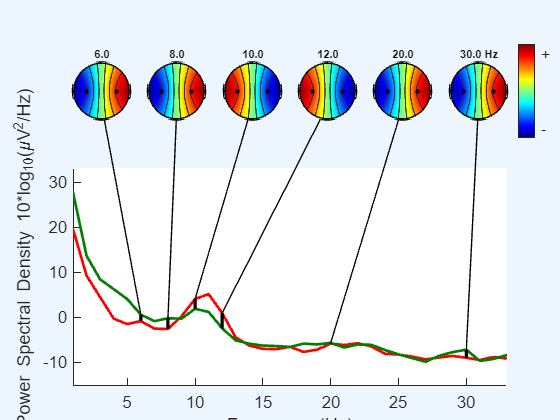

base_tlen = [0 8];

[spectra_base, freqs_base, specstd_base] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C3', 'C4'}}, "", [], 'on');

### Checking correlation across 1sec time windows of full-epoch length baselin trials (n=12, t=8sec), using spectrogram (time-frequency decomposition)

EEG_baseline = pop_select(EEG, 'channel', {'C3'});

Removing 31 channel(s)...


spectrum_base_cell = cell(3,8);

for t = 1:8
    tlen = t-1:t;
    EEG_base_window = pop_epoch(EEG_baseline, {'1000'}, tlen, 'verbose', 'off');
    [ersp,~,~,times,freqs,~,~] = pop_newtimef(EEG_base_window, 1, 1, tlen*1000, [3 0.5], ...
                'freqs', [4 30], 'nfreqs', 27, 'plotitc', 'off', 'plotersp', 'off', 'verbose', 'off', 'baseline', NaN);

    for f = 1:3
        mean_ers = mean(ersp(freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end), :));
        spectrum_base_cell{f,t} = mean_ers;
    end
end

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Value of timesout must be <= frames-winsize, timeout adjusted to 112


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Value of timesout must be <= frames-winsize, timeout adjusted to 112


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Value of timesout must be <= frames-winsize, timeout adjusted to 112


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Value of timesout must be <= frames-winsize, timeout adjusted to 112


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Value of timesout must be <= frames-winsize, timeout adjusted to 112


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Value of timesout must be <= frames-winsize, timeout adjusted to 112


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Value of timesout must be <= frames-winsize, timeout adjusted to 112


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Value of timesout must be <= frames-winsize, timeout adjusted to 112



newCell = cell(3, 1);
for i = 1:3
    % Concatenate along the second dimension to create a 7x21 matrix
    newCell{i} = cat(1, spectrum_base_cell{i, :})';
end
spectrum_base_cell = newCell;

for i = 1:3
    R = corrcoef(spectrum_base_cell{i})
end

R =     1.0000    0.6386    0.1078    0.6656    0.4210    0.7568    0.1618    0.0340
    0.6386    1.0000   -0.5424    0.9253    0.8645    0.1528   -0.6386   -0.5940
    0.1078   -0.5424    1.0000   -0.6616   -0.8434    0.6925    0.7385    0.9857
    0.6656    0.9253   -0.6616    1.0000    0.9485    0.0655   -0.4971   -0.7098
    0.4210    0.8645   -0.8434    0.9485    1.0000   -0.2377   -0.6462   -0.8793
    0.7568    0.1528    0.6925    0.0655   -0.2377    1.0000    0.4933    0.6479
    0.1618   -0.6386    0.7385   -0.4971   -0.6462    0.4933    1.0000    0.7344
    0.0340   -0.5940    0.9857   -0.7098   -0.8793    0.6479    0.7344    1.0000


R =     1.0000   -0.9923    0.5992    0.9814    0.9491    0.9473   -0.9793   -0.9497
   -0.9923    1.0000   -0.6249   -0.9937   -0.9134   -0.9298    0.9576    0.9641
    0.5992   -0.6249    1.0000    0.6997    0.4707    0.3312   -0.4809   -0.7952
    0.9814   -0.9937    0.6997    1.0000    0.8920    0.8928   -0.9347   -0.9817
    0.9491   -0.9134    0.4707    0.8920    1.0000    0.9573   -0.9880   -0.8342
    0.9473   -0.9298    0.3312    0.8928    0.9573    1.0000   -0.9815   -0.8091
   -0.9793    0.9576   -0.4809   -0.9347   -0.9880   -0.9815    1.0000    0.8775
   -0.9497    0.9641   -0.7952   -0.9817   -0.8342   -0.8091    0.8775    1.0000


R =     1.0000   -0.2633    0.0018   -0.5653   -0.2355    0.4926   -0.0851   -0.4618
   -0.2633    1.0000    0.9374    0.2242    0.3766   -0.8974   -0.3770    0.9614
    0.0018    0.9374    1.0000    0.0627    0.3533   -0.7431   -0.5456    0.8301
   -0.5653    0.2242    0.0627    1.0000    0.8851   -0.0863    0.5306    0.4537
   -0.2355    0.3766    0.3533    0.8851    1.0000   -0.0655    0.3104    0.5118
    0.4926   -0.8974   -0.7431   -0.0863   -0.0655    1.0000    0.3976   -0.8838
   -0.0851   -0.3770   -0.5456    0.5306    0.3104    0.3976    1.0000   -0.1835
   -0.4618    0.9614    0.8301    0.4537    0.5118   -0.8838   -0.1835    1.0000


`For subject 002: Time window 4 and 5 have highest positive correlation, consistently >= 0.88 across all frequency bands. Using baseline epoch 3000-5000ms for further analysis.`

## Stim epochs

### Plot power spectrum density of conditions

% stim_epoch = [0 3];
% for i = 1:4
%     cond_plot_spectra(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_epoch, ...
%         freqs_array, elec_plot, markerLabel(i)+"-PSD", [filepath plot_folder], 'off');
% end

### Compute PSD of stim epochs

`spectra  = (nchans,nfreqs) power spectra (mean power over epochs), in dB`

`freqs is array of frequency ( 0 - 64 Hz)`

`specstd  = spectrum standard deviation in dB`

spectra_stim = [];
for i = 1:4
    [spectra,freqs,specstd] = cond_plot_spectra(EEG, num2cell(markerVal_num(1:8)), stim_epoch, ...
        freqs_array, {{'C3'}}, "", [], 'off');
end

Power spectra is the amplitude of each frequency in the epoched data. This however does not output power value with time. 

The output tfdata from newtimef can do so. However, it's necessary to convert complex values to real numbers (the magnitude for any time, frequency, electrode, and trial can be calculated).

Event related spectrogram can be generated from Time-frequency decomposition (newtimef), but with "No baseline" option.

figure(); plot(freqs, spectra);


alpha_l_bp = mean(spectra(freqs >= 8 & freqs <= 10));
alpha_h_bp = mean(spectra(freqs >= 10 & freqs <= 13));
beta_bp = mean(spectra(freqs >= 13 & freqs <= 30));
theta_bp = mean(spectra(freqs >= 4 & freqs <= 8));
bp = [ alpha_l_bp alpha_h_bp beta_bp];

band_names = ["low alpha" "high alpha" "beta"];
figure(); bar(bp); set(gca, 'xticklabel', band_names);

### Compute band power: mean and std 

for C3/C4, theta band might not be significantly relevant

theta_band = {4:8};
alpha_l_band = {8:10};
alpha_h_band = {10:13};
beta_band = {13:30};
freq_bands = [alpha_l_band, alpha_h_band, beta_band];
times_range = [0.4 1.4]; % time range for mu band


bandpower_cell = cell(3,2); % 3 freqs bands and 2 channels

for f=1:length(freq_bands)
    for chan = 1:length(chan_names)
        cell_cond = cell(2, 4); % 2 rows (mean and std) and 4 conditions
        for i = 1:4
            [spectra,freqs,specstd] = cond_plot_spectra(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), times_range, ...
                freqs_array, {chan_names(chan)}, "", [], 'off');
    
            mean_bp = mean(spectra(freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end)));
    
            band_specstd = specstd(freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end));
            std_bp = sqrt(sum(band_specstd.^2)/length(freq_bands)) ;
            
            cell_cond{1,i} = mean_bp; cell_cond{2,i} = std_bp;
        end
        bandpower_cell{f,chan} = cell_cond;
    end
end



### Try out tfdata from newtimef

% stim_tlen = [-1 3];
% EEG_cond_epoch = cond_epoch(EEG, num2cell(markerVal_num(1:8)), stim_tlen);
% EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
% 
% 
% [ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
%      pop_newtimef(EEG_cond_chan, 1, 1, [-1 2]*1000, [3 0.5], ...
%                 'freqs', [4 30], 'plotitc', 'off', 'plotersp', 'off','erspmax', 5, 'verbose', 'off');
% 
% tfdata_stim = tfdata(freqs >= 8 & freqs <= 10, times >= 0, :);
% [~, ntimes, ntrial] = size(tfdata_stim);


I dont know how to process complex values of tfdata

### Plot time-freq decomposition and ERSP (Event Related Spectral Perturbation)

Processing using C3 and C4 for now. Can look at ICA component later

stim_tlen = [-1 3];
ersp_color_lim = 5;
alpha = 0;
% for i = 1:4
%     cond_ersp(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen, ...
%         [-1 2], [4 30], {'C3', 'C4'}, ersp_color_lim, alpha,  markerLabel(i) + "-ERSD", [filepath plot_folder], 'on');
% end

% alpha = 0.05;
% for i = 1:4
%     cond_ersp(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen, ...
%         [-1 2], [4 30], {'C3', 'C4'},ersp_color_lim, alpha,  markerLabel(i) + "-ERSD-alpha0.05",[filepath plot_folder], 'on');
% end

## Plot ERSP by frequency bands and conditions

i=1
alpha = 0.05;
[ersp_out, times, freqs_out, erspboot_out ] = cond_ersp(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen, ...
        [-1 2], [4 30], {'C3', 'C4'}, ersp_color_lim, alpha,  [], [], 'off');
ersp_C3 = ersp_out{1,1}; 
erspboot_C3 = erspboot_out {1,1};


theta: 4-8Hz, alpha/mu: 8-13 Hz, beta: 13-30Hz

% ersp_C3_bands = {};
% mean_ersp_bands = {}; std_ersp_bands = {};ersp_band
% for band = [theta_band, alpha_band, beta_band]
%     ersp_band = ersp_C3(ismember(freqs_out , band{1}),:)
%     ersp_C3_bands = [ersp_C3_bands, ersp_band]; % comment out if unused
% 
%     mean_ersp_bands = [mean_ersp_bands, mean(ersp_band, 1)]; 
%     std_ersp_bands = [std_ersp_bands, std(ersp_band, 1)]; 
% end
% mean_ersp_bands

**Boni 2023: **

theta: 4-8 Hz

Low alpha: 8-10 Hz

HIgh alpha: 10-13 Hz

Beta: 13-30 Hz

theta_band = {4:8};
alpha_band = {8:13};
beta_band = {13:30};
band_colors = ['b','r','g'];
band_names = ["theta", "alpha", "beta"];
chan_names = {'C3', 'C4'};
axgrid = [4,2];
cond_label_full = ["Human agent, left-hand actions", "Human agent, right-hand actions", "Robot agent, left-hand actions", "Robot agent, right-hand actions"];

figure; tclMain = tiledlayout(axgrid(1),1);
tcl = gobjects(1, axgrid(1));
ax = gobjects(axgrid);
for i = 1:4
    [ersp_out, times, freqs_out, erspboot_out ] = cond_ersp(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen, ...
        [-1 2], [4 30], {'C3', 'C4'}, ersp_color_lim, alpha,  [], [], 'off');
    
    tcl(i) = tiledlayout(tclMain,1,axgrid(2));
    tcl(i).Layout.Tile = i; 
    
    for chan = 1:length(ersp_out)
        ersp_chan = ersp_out{1, chan};
        mean_ersp_bands = {}; std_ersp_bands = {};
        for band = [theta_band, alpha_band, beta_band]
            ersp_band = ersp_chan(ismember(freqs_out , band{1}),:);
            mean_ersp_bands = [mean_ersp_bands, mean(ersp_band, 1)];
            std_ersp_bands = [std_ersp_bands, std(ersp_band, 1)];
        end
        
        nexttile(tcl(i))
        plot_ersp_band(times, mean_ersp_bands, std_ersp_bands, i, band_colors, ...
            band_names, chan_names(chan))
    end
    title(tcl(i), cond_label_full{i},'fontweight','bold')
end
lgd = legend('FontSize', 8); lgd.NumColumns = 3; 
lgd.Layout.Tile = 'south';


### Check out absolute scale ersp (by setting 'scale' to 'abs')

% [ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
%      pop_newtimef(EEG_cond_chan, 1, 1, [-1 2]*1000, [3 0.5], ...
%                 'freqs', [4 30], 'plotitc', 'off', 'plotersp', 'off','erspmax', 5, 'verbose', 'off', 'scale', 'abs');
% 
% ersp_stim = ersp(freqs >= 8 & freqs <= 10, times >= 0);
% 
% ersp_band = cell(1,4);
% for i=1:4
%     ersp_stim = ersp(freqs >= freq_bands{i}(1) & freqs <= freq_bands{i}(end), times >= 0);
%     ersp_band{i} = reshape(ersp_stim, [], 1);
% end
% figure(); 
% subplot(1,2,1); distributionPlot(ersp_band);

### Violin plot

band_names = ["theta", "low alpha", "high alpha", "beta"];
times_range = [400 1400]; % time range for mu band
ersp_all = cell(4,2);

figure();
tclMain = tiledlayout(axgrid(1),1);
tcl = gobjects(1, axgrid(1));
ax = gobjects(axgrid);

for i=1:length(markerLabel)
    [ersp_out, times, freqs_out, ~ ] = cond_ersp(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen, ...
        [-1 2], [4 30], {'C3', 'C4'}, ersp_color_lim, alpha,  [], [], 'off');
    
    tcl(i) = tiledlayout(tclMain,1,axgrid(2));
    tcl(i).Layout.Tile = i; 

    for chan=1:length(ersp_out)
        ersp_chan = ersp_out{1, chan};
        ersp_band = cell(1,4);

        for j = 1:length(freq_bands)
            ersp_band{j} = reshape(ersp_chan(freqs >= freq_bands{j}(1) & freqs <= freq_bands{j}(end), times >= times_range(1) & times <= times_range(2)), [], 1);
        end
        ersp_all{i, chan} = ersp_band;
        
        nexttile(tcl(i))
        distributionPlot(ersp_band); title(chan_names{chan}); set(gca, 'xticklabel', band_names); ylabel('ERDS (dB)'); xlabel('')
    end
    title(tcl(i), cond_label_full{i},'fontweight','bold')
end
% lgd = legend('FontSize', 8); lgd.NumColumns = 3; 
% lgd.Layout.Tile = 'south';

## Tryout Event related Spectrogram

**Angelini 2018:**

For each accepted and cleaned epoch, time-frequency transforms were computed for each electrode in the frequency range from 5 to 32 Hz (55 output frequencies, frequency resolution 0.5 Hz), by means of a Morlet wavelet with the number of cycles increasing linearly with frequency (from 4 cycles at the lowest to 15.36 cycles at the highest frequency)

base_tlen = [2 4];

[spectra_base, freqs_base, specstd_base] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C3'}}, "", [], 'on');

for i=1:4
    % epoching
    stim_tlen = [0 3];
    EEG_cond_epoch = pop_epoch(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen);
    EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
    
    % Compute event-related spectrogram (ERS)
    [ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
         pop_newtimef(EEG_cond_chan, 1, 1, stim_tlen*1000, [4 15.36], ...
                    'freqs', [4 30], 'plotitc', 'off', 'plotersp', 'off', 'verbose', 'off', 'baseline', NaN);
    
    % Baseline correction
    erspec = zeros(size(ersp));
    for row = 1:height(ersp)
        erspec(row, :) = ersp(row, :) / spectra_base(freqs_base == freqs(row));
    end
    figure();
    imagesc(times, freqs, erspec)
    axis xy; colorbar; xlabel('Time (ms)'); ylabel('Frequency (Hz)');
    title('Absolute power ratio wrt baseline activity');
end

*In order to minimize sensitivity to outlier and noisy trials, each single-trial time-frequency transform was normalized by dividing each frequency by the mean spectral power of the same frequency over the full-epoch length. *

*Afterward, a 300 ms prestimulus period within the ITI (from −1150 to −850 ms before video clip onset) served as a baseline, and for each participant and condition, averaged spectral data were baseline corrected by dividing each time-frequency point value by average spectral power of the baseline at the same frequency. *

*The ratio was used to account for individual variability in overall EEG power. Resulting data were expressed as absolute power ratio with respect to baseline activity: an absolute ratio value of 1 indicated no difference relative to the baseline, values < 1 represented desynchronization (i.e., EEG power reduction) and values> 1 represented synchronization (i.e., EEG power increase)*

for i=1:length(markerVal_num)
    % epoching
    stim_tlen = [0 3];
    EEG_cond_epoch = pop_epoch(EEG, num2cell(markerVal_num(i)), stim_tlen, 'verbose', 'off');
    EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});


    % compute mean spectral power for each frequency
    [spectra,freqs_stim,specstd] = cond_plot_spectra(EEG, num2cell(markerVal_num(i)), stim_tlen, ...
        freqs_array, {{'C3'}}, "", [], 'off');

    % Compute event-related spectrogram (ERS)
    [ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
         pop_newtimef(EEG_cond_chan, 1, 1, stim_tlen*1000, [4 0.5], ...
                    'freqs', [4 30], 'plotitc', 'off', 'plotersp', 'off', 'verbose', 'off', 'baseline', NaN);

    ers_norm = zeros(size(ersp));
    for row = 1:height(ersp)
        ers_norm(row, :) = ersp(row, :) / spectra(freqs_stim == freqs(row));
    end


end

## Statistical Analysis

**Urget et al 2013**: For mu, mean alpha power in the time window of the mu attenuation (400–1400 ms after stimulus onset) was extracted for each condition (Agent) and channel (C3: left hemisphere; C4: right hemisphere), and entered into a *3(Agent) × 2 (Hemisphere)* repeated measures ANOVA. For beta, the mean power in the time window of the beta increase (150400 ms after stimulus onset) was extracted for each condition (Agent) and channel (F3: left hemisphere; F4: right hemisphere) and entered into a *3(Agent) × 2 (Hemisphere)* repeated measures ANOVA.

**Boni 2023:**

The desynchronisation of the μ rhythm in central electrodes (C3 and C4) during action observation was analysed within three frequency bands: Lowalpha (8–10 Hz), high-alpha (10–13 Hz), and beta (13–30 Hz) [31,32]. In each patient, the power of these frequency bands was averaged within three-time epochs: (1) PRE-ONSET (PO), corresponding to 1 s of the countdown before the video’s onset; (2) STILL HANDS (SH), corresponding to 1 s of the static image at the beginning of the videos; (3) ACTION OBSERVATION (AO), corresponding to 2 s of action execution, starting at movement onset.

- A **repeated-measures ANOVA **was performed on the** spectral power** of the low-alpha, high-alpha, and beta frequency bands with factors WEEK (first, second, and third), SIDE (lesioned, and non-lesioned hemisphere), and EPOCH (PO, SH, AO). Significant main effects were evaluated by means of post-hoc multiple comparisons with Bonferroni’s correction. 

- To further investigate the effect of SIDE during AO, **independent-sample t-tests** were conducted on each frequency band, comparing **power suppression** between the lesioned and the non-lesioned hemisphere both in mild/moderate and severe subgroups.

**For this study, we have factors: EPOCH (BL, AO, AE), ACTOR (human, robot), SIDE (right-hand ad left-hand actions). **

**Further investigate in the effects of ACTOR and SIDE during AO and AE**

### ANOVA to compare spectral power

Steps: extract spectral power of frequency bands, compute mean power in the time window of the epoch 

**Repeated measures ANOVA**: Measuring the mean scores of subjects under three different conditions

between-subject variables: (not considered here, but in a larger-size study, these can be age, age, gender, ethnicity, etc.)

within-subject variables: actor, side, channel, (epoch)

Store data in table array

bandpower_cell: 3x2 cell array - 3 frequency bands, 2 channels, each element is a cell array of size 2x4 (2 rows are mean and std of power spectra, 4 colums are conditions)

band_names = ["low alpha", "high alpha", "beta"];

mean_bp =[];
for c = 1:size(bandpower_cell, 2)
    for f = 1:size(bandpower_cell, 1)
        mean_bp = [mean_bp cell2mat(bandpower_cell{f,c}(1,:))];
    end
end
mean_bp = reshape(mean_bp(:), [4 6])';

T = table( repelem(["C3";"C4"], [3 3]), repmat(["F1"; "F2";"F3"], 2,1), ...
    mean_bp(:,1), mean_bp(:,2), mean_bp(:,3), mean_bp(:,4),...
    'VariableNames', {'CHAN', 'FBAND', 'COND1', 'COND2', 'COND3', 'COND4'});
% T.CHAN = categorical(T.CHAN);

within = table( ); 
within.Var1 = repelem(["human"; "robot"], [2 2]);
within.Var2 = repmat(["left"; "right"], 2,1);
within.Properties.VariableNames = {'ACTOR', 'SIDE'};
within.ACTOR = categorical(within.ACTOR);
within.SIDE = categorical(within.SIDE);

Fit a repeated measures model. Also specify the within-subject design matrix.

rm = fitrm(T, 'COND1-COND4 ~ CHAN+FBAND', 'WithinDesign',within);
[ranovatbl,A,C,D] = ranova(rm,'WithinModel','ACTOR + SIDE')

Compute significance effect for each frequency band

mean_bp = [];
for f = 1:size(bandpower_cell, 1)
    for c = 1:size(bandpower_cell, 2)
        mean_bp = [mean_bp cell2mat(bandpower_cell{f,c}(1,:))];
    end
end
mean_bp = reshape(mean_bp(:), [4 6])';

for f = 1:3
    band_names(f)
    T = table( ["C3";"C4"], mean_bp((f-1)*2+1:f*2,1), mean_bp((f-1)*2+1:f*2,2), mean_bp((f-1)*2+1:f*2,3), mean_bp((f-1)*2+1:f*2,4),...
        'VariableNames', {'CHAN', 'COND1', 'COND2', 'COND3', 'COND4'});
    
    within = table( ); 
    within.Var1 = repelem(["human"; "robot"], [2 2]);
    within.Var2 = repmat(["left"; "right"], 2,1);
    within.Properties.VariableNames = {'ACTOR', 'SIDE'};
    within.ACTOR = categorical(within.ACTOR);
    within.SIDE = categorical(within.SIDE);
    
    rm = fitrm(T, 'COND1-COND4 ~ 1', 'WithinDesign',within);
    [ranovatbl,A,C,D] = ranova(rm,'WithinModel','ACTOR + SIDE')

end

### **t-tests to compare the power suppression**

**The output ersp from time-freq decompostion or ERSP (newtimef): (nfreqs,timesout) matrix of log spectral diffs from baseline (in dB log scale or absolute scale). Log scale and absolute scale didnt show any different on plots (which is weird?).**

**The output (Event-elated spectra perturbation, ERSP) will be used for analysis (Boni 2023)**

ersp_all - nested cell array structure: 4 rows - conditions (actor/side), 2 columns - channels (C3, C4), each entry is a cell array of 4 double arrays of ERSP for 4 freq bands.

function [ersp_out, times, freqs_out, erspboot_out ] = cond_ersp(EEG, events_cell, tlen, sub_epoch_len, freqs, channels, erspmax, alpha, plottitle, filepath, toPlot)
    EEG_cond_epoch = cond_epoch(EEG, events_cell, tlen);
    if length(channels) == 1
        EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', channels);
        if alpha ~= 0
            if string(toPlot) == "off"
                [ersp_out,~,~,times,freqs_out,erspboot_out,~,~] = ...
                pop_newtimef(EEG_cond_chan, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            else
                figure;
            [ersp_out,~,~,times,freqs_out,erspboot_out,~,~] = ...
                pop_newtimef(EEG_cond_chan, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            end
            else
            figure; 
            [ersp_out,~,~,times,freqs_out,erspboot_out,~,~] = ...
                pop_newtimef(EEG_cond_chan, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot,'erspmax', erspmax, 'verbose', 'off');
        end
    
    elseif length(channels) == 2
        EEG_cond_chan1 = pop_select( EEG_cond_epoch, 'channel', channels(1));
        EEG_cond_chan2 = pop_select( EEG_cond_epoch, 'channel', channels(2));

        if alpha ~= 0
            if string(toPlot) == "off"
                [ersp1,~,~,times,freqs_out,erspboot1,~,~] = ...
                pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
                [ersp2,~,~,times,freqs_out,erspboot2,~,~] = ...
                pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            else

            figure; sgtitle(plottitle)
            subplot(2,1,1); 
            [ersp1,~,~,times,freqs_out,erspboot1,~,~] = ...
                pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            title(string(channels(1)))
            subplot(2,1,2); 
            [ersp2,~,~,times,freqs_out,erspboot2,~,~] = ...
                pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            title(string(channels(2)))
            end
        else 
            if string(toPlot) == "off"
                [ersp1,~,~,times,freqs_out,erspboot1,~,~] = ...
                pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'verbose', 'off');
                [ersp2,~,~,times,freqs_out,erspboot2,~,~] = ...
                pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'verbose', 'off');
            else

            figure; sgtitle(plottitle)
            subplot(2,1,1); 
            [ersp1,~,~,times,freqs_out,erspboot1,~,~] = ...
                pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'verbose', 'off');
            title(string(channels(1)))
            subplot(2,1,2); 
            [ersp2,~,~,times,freqs_out,erspboot2,~,~] = ...
                pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'verbose', 'off');
            title(string(channels(2)))
            end
        end
        save_figures(filepath, plottitle, toPlot)
        ersp_out = {ersp1, ersp2}; erspboot_out = {erspboot1, erspboot2};
    end

end
%=================================================================
% function 

% ===================================================
function [spectra,freqs,specstd] = cond_plot_spectra(EEG, events_cell, tlen, freqs, chanlocs, plottitle, filepath, toPlot)
    EEG_cond_epoch = cond_epoch(EEG, events_cell, tlen);
    
    if length(chanlocs) == 1
        EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', chanlocs{1});
        figure; title(plottitle);
        [spectra,freqs,speccomp,contrib,specstd] = pop_spectopo(EEG_cond_chan, 1, tlen*1000, 'EEG',...
            'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', toPlot, 'verbose', 'off');

    elseif length(chanlocs) == 2
        EEG_cond_RH = pop_select( EEG_cond_epoch, 'channel',chanlocs{1});
        EEG_cond_LH = pop_select( EEG_cond_epoch, 'channel',chanlocs{1}); 
        figure; sgtitle(plottitle);
        subplot(211); 
        pop_spectopo(EEG_cond_RH, 1, tlen*1000, 'EEG',...
            'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', toPlot, 'verbose', 'off');
        subplot(212); 
        pop_spectopo(EEG_cond_LH, 1, tlen*1000, 'EEG',...
            'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', toPlot, 'verbose', 'off');
    end
    % save_figures(filepath, plottitle, toPlot)
end


%===================================================
function OUTEEG = cond_epoch(EEG, events_cell, tlen)
    % events_cell
    EEG_epoch = pop_epoch(EEG, events_cell, tlen, 'verbose', 'off');
    OUTEEG = pop_rmbase(EEG_epoch, [0 0.5]*1000);

end


function save_figures(filepath, plottitle, toPlot)
    if string(toPlot) == "on"
        savefig(fullfile(filepath, plottitle+".fig"));
        saveas(gcf, fullfile(filepath, plottitle+".png")) 
    end
end


%=================================================================
function plot_ersp_band(times, mean_ersp_bands, std_ersp_bands, cond_num, band_colors, band_names, chan_name)
    hold on;
    xline(0, 'k--','Alpha', 0.5, 'HandleVisibility', 'off')
    yline(0, 'k--','Alpha', 0.5, 'HandleVisibility', 'off')
    for i = 1:length(mean_ersp_bands)
        plot(times, mean_ersp_bands{1,i}, 'Color', band_colors(i), 'DisplayName', band_names(i))
        fill([times, fliplr(times)], [mean_ersp_bands{1,i} + std_ersp_bands{1,i}, ...
            fliplr(mean_ersp_bands{1,i} - std_ersp_bands{1,i})], band_colors(i), 'EdgeColor', 'none', ...
            'FaceAlpha', 0.2, 'HandleVisibility', 'off');
    end
    if cond_num == 1
        title(chan_name); 
    end
    xlim([min(times), max(times)]);
    ylabel('ERDS (dB)'); xlabel('time [ms]')
    hold off;
end













